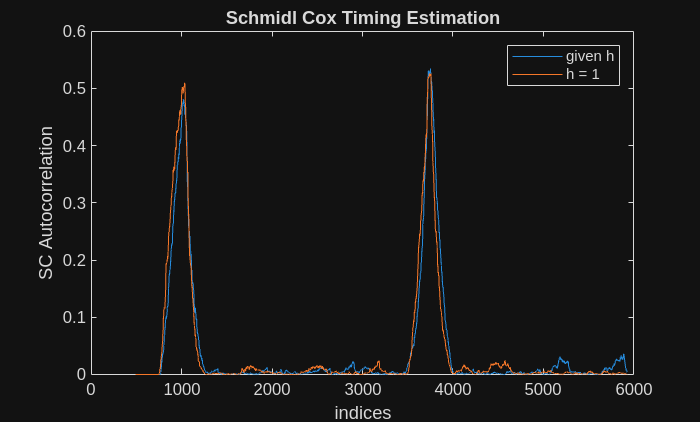

%%Question1

clear all; close all; clc;
%%%%% OFDM parameters %%%%%
params.del_f = 1e4;              % subcarrier spacing = 10kHz
params.numCarriers = 512;        % fft size = 512
params.prefixDuration = 6.25e-6; % CP duration =6.25 mus

params.sampleRate = params.del_f * params.numCarriers;
params.prefixLength = round(params.prefixDuration * params.sampleRate);
params.blockDuration = (params.numCarriers + params.prefixLength) / params.sampleRate;
params.preamblePeriodicity = 5;               % Frame size = 5
params.guardTones = [241:256 -255:-241];   % Guard bands
params.DCSubcarrier = [0];                   % DC carrier
params.pilots = false;
params.pilotPeriodicity = 8;

%%%% Channel Parameters %%%%%
params.pathGains = [-3 0 -1 -4 -9 -17];
params.delays = [0 7 13 18 21 26];
% Taps = 16;
% params.delays = 1:Taps;
% params.pathGains = zeros([1 Taps]);

params.CFO = 28.65e3;                      % Maximum offset = 28.65kHz
% params.CFO = 0;                      % Maximum offset = 28.65kHz
params.SNR = 6;

%%%%% Modulation parameters %%%%%
params.modulationType = 'QAM';
params.modulationOrder = 4;
params.numFrames = 2;

% params.numCarriers = 16;
% params.prefixLength = 4;  
% params.guardTones = [-7:-6 7:8];

S = OFDM.generateOFDMframe(params);
s = OFDM.modulate(S, params);
[r, h] = OFDM.channel(s, params);
r = [zeros([1 1000]) r];
% r = s;
z = OFDM.SCcorr(r, params);
figure; plot(abs(z));
hold on;

Taps = 1;
params.delays = 1:Taps;
params.pathGains = zeros([1 Taps]);

S = OFDM.generateOFDMframe(params);
s = OFDM.modulate(S, params);
[r, h] = OFDM.channel(s, params);
r = [zeros([1 1000]) r];
% r = s;
z = OFDM.SCcorr(r, params);

plot(abs(z));
legend('given h', 'h = 1')
% ylim([0 2])
% xlim([3416 4106])
xlabel('indices')
ylabel('SC Autocorrelation')
title('Schmidl Cox Timing Estimation')

% ylim([0.015 1.091])
% size(z)